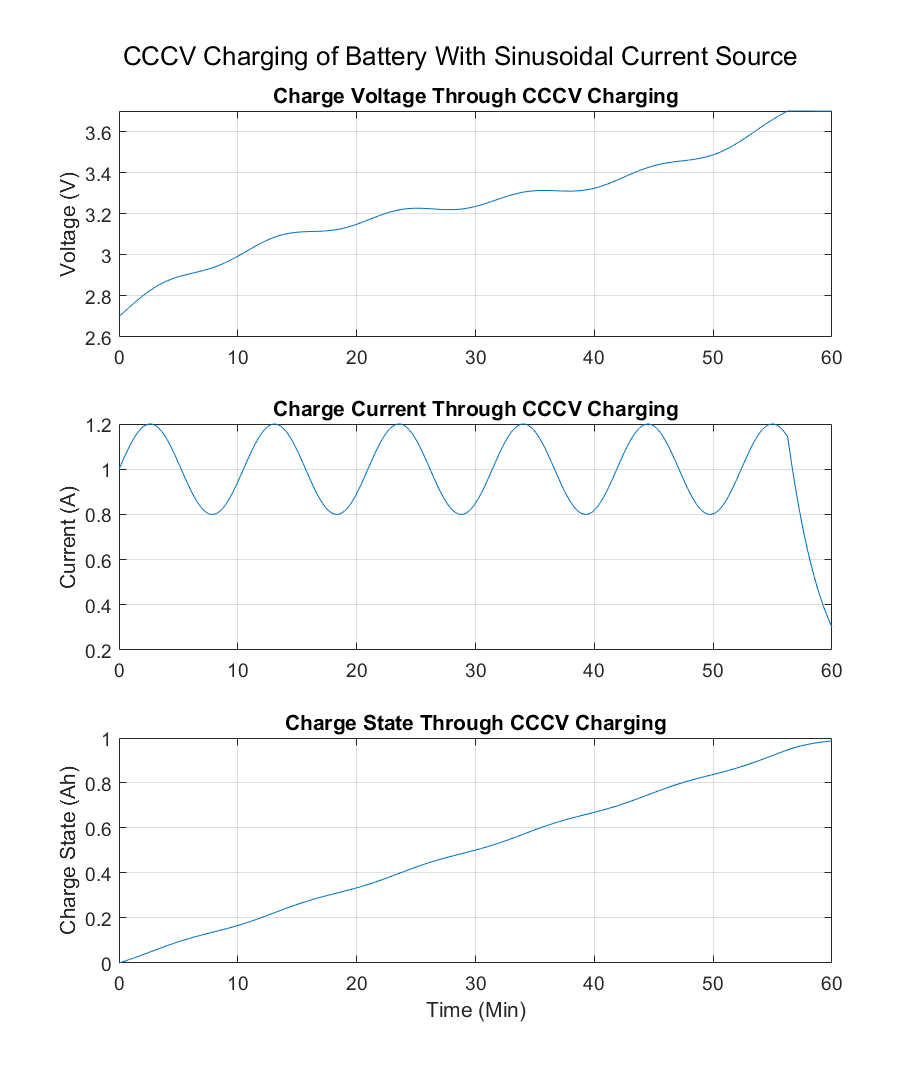

chargeTimehr=1;

Vmax=3.7;
U=3600;
ESR=0.1;
t=0:3600*chargeTimehr;
I=zeros(length(t),1);
V=zeros(length(t),1);
x=zeros(length(t),1);

V(1)=2.7;
I(1)=1+0.2*sin(0.01*0);
x(1)=0;

for i=2:length(t)
    I(i)=req7curr(x(i-1),t(i),Vmax);
    x(i)=x(i-1)+(I(i)/U);
    V(i)=(2.6+2.35*x(i)-3.75*x(i)^2+2.5*x(i)^3)+ESR*I(i);

end

t2=t/60;
fig2=figure('Position', [100, 100, 1024, 1200]);
sgtitle("CCCV Charging of Battery With Sinusoidal Current Source")
subplot(3,1,1);
h1=plot(t2,V);
title("Charge Voltage Through CCCV Charging")
%xlabel("Time (s)")
ylabel("Voltage (V)")
grid on
hold on

subplot(3,1,2);
h2=plot(t2,I);
title("Charge Current Through CCCV Charging")
%xlabel("Time (s)")
ylabel("Current (A)")
grid on

subplot(3,1,3);
h3=plot(t2,x);
title("Charge State Through CCCV Charging")
xlabel("Time (Min)")
ylabel("Charge State (Ah)")
grid on
hold off